clear; close; clc;

%fplot(@(x) )


nPoints = 21;

s2 = 1 / cos(pi/6);
s6 = (4 - s2) * sin(pi/6);



corners = ...
    [
    -2, 0
    -1, 0
    0, 4
    s6 * cos(pi/6), s2 + s6 * sin(pi/6)
    ]

corners =    -2.0000         0
   -1.0000         0
         0    4.0000
    1.2321    1.8660


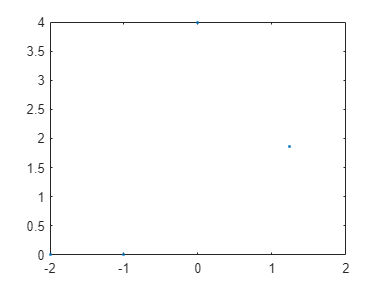


plot(corners(:,1), corners(:,2), '.')

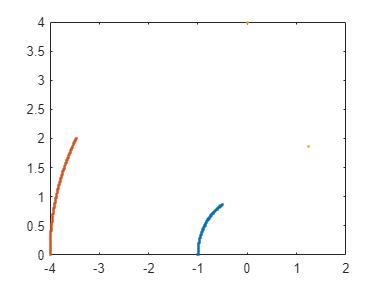



t_inner = linspace(0,pi/3)';
inner = thirdArc(-1,t_inner);

t_outer = linspace(0,pi/6)';
outer = thirdArc(-4,t_outer);

plot(inner(:,1), inner(:,2), '.');
hold on;
plot(outer(:,1), outer(:,2), '.');
hold on;
plot(corners(3:4,1), corners(3:4,2), '.')
hold off;



clear t;

syms t;
sympref("HeavisideAtOrigin",.5); % to make it well conditioned at overlap

x_ic = corners(4,1);

% make the arc - note this is naturally paramterized 
xInnerArc = cos(t-pi);
yInnerArc = -sin(t-pi);

% now arc length parameterization
% semi circ is arc len paramterized already
% line is needs be scaled by 1/mag to be arc length parameterized 
magInner = 5585394183300118827385933267443^(1/2)/1125899906842624

magInner = 2.0991

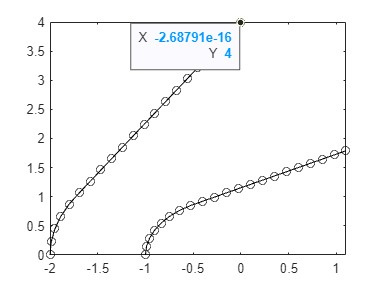

xInnerLine = -1/2 + ((x_ic + 1/2) / (2 - pi/3)) * (t - pi/3)/magInner;
yInnerLine = sqrt(3)/2 + tan(pi/6) * (xInnerLine + 1/2);

t_s = pi/3;
xInner = xInnerArc * heaviside(-t+t_s) + xInnerLine * heaviside(t-t_s);
yInner = yInnerArc * heaviside(-t+t_s) + yInnerLine * heaviside(t-t_s);

fInner = [xInner, yInner];

% find the total arc length
r_inner = 1;
theta_inner = pi/3;
y_ic = corners(4,2);
AlenInner =  r_inner * theta_inner + sqrt((x_ic + 1/2)^2 + (y_ic - sqrt(3/2))^2);


% outer

% arc length parameterised circle
xOuterArc = 2 * cos(t/2-pi);
yOuterArc = -2 * sin(t/2-pi);

% compute line parameterised by arc length
x1 = -2 * sqrt(3)/2;
y1 = 2 * 1/2;

magOut = 4093431634936677/1125899906842624; % adjustment factor for acr length parameterization

xOuterLine = x1 - x1/(2*(1-pi/6)) * (t - 2*pi/6)/(magOut);
yOuterLine = y1 + tan(pi/3) * (xOuterLine-x1);

% assemble the final function
t_s = 2*pi/6;
xOuter = xOuterArc * heaviside(-t+t_s) + xOuterLine * heaviside(t-t_s);
yOuter = yOuterArc * heaviside(-t+t_s) + yOuterLine * heaviside(t-t_s);

fOuter = [xOuter, yOuter];

% find the total arc length
r_outer = 2;
theta_outer = pi/6;
x_oc = corners(3,1);
y_oc = corners(3,2);
AlenOuter =  r_outer * theta_outer + sqrt((x_oc - x1)^2 + (y_oc - y1)^2);
%AlenOuter = 4*pi/6 + sqrt((x_oc - x1)^2 + (y_oc - y1)^2)

% plot inner
timeInner = linspace(0,AlenInner, nPoints)'; % unsure of what total arc length to use yet
% it will be r*theta + (Deltax^2+Deltay^2)^(1/2)

points = double(subs(fInner,t,timeInner));
plot(points(:,1), points(:,2), 'k- o');
hold on;


% plot outer
timeOuter = linspace(0,AlenOuter, nPoints)'; % unsure of what total arc length to use yet
% it will be r*theta + (Deltax^2+Deltay^2)^(1/2)

points = double(subs(fOuter,t,timeOuter));
plot(points(:,1), points(:,2), 'k- o');
hold on;